% Modelling ML

% Load train and test data
train = readtable('train.csv');
test = readtable('test.csv');

% Convert to matrix
train = train{:,:};
test = test{:,:};

% Split into target and features 
X_train = train(:, 2:end);
y_train = train(:, 1);

X_test = test(:, 2:end);
y_test = test(:, 1);

rng(1) % for reproducability

% ********** 1) Train / Test Baseline Models **********

% 1a) Baseline Decision Tree with default parameters
% Train
dt_base = fitctree(X_train, y_train, 'Reproducible', 1, 'prior', 'empirical', 'MaxNumSplits', 10, 'MinLeafSize', 1);
% Evaluate baseline tree
test_model(dt_base, X_test, y_test)

accuracy = 0.9409

precision = 0

recall = 0

specificity = 0.9946

fb = 0

% 1b) Baseline KNN
% Train
knn_base = fitcknn(X_train, y_train, 'Prior', 'empirical', 'NumNeighbors', 1, 'Distance', 'euclidean', 'DistanceWeight', 'equal'); 
% Evaluate baseline knn
test_model(knn_base, X_test, y_test)

accuracy = 0.9104

precision = 0.1429

recall = 0.1321

specificity = 0.9548

fb = 0.1373

% ********** 2) Hyperparameter Tuning Models (CV = k-fold, loss = accuracy) **********

% CV SPLITS: Define a random partition of data (fixes the train and validation set)
[nrow, ncol] = size(X_train);
c = cvpartition(nrow,'KFold', 20);

% DECISION TREE: Define vars and range
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical'); % default: 'empirical'
MaxNumSplit = optimizableVariable('MaxNumSplit',[1, 30],'Type','integer');  % default: 10
MinLeafSize = optimizableVariable('MinLeafSize', [1, 30], 'Type', 'integer');  % default: 1

ParamsDT = [prior, MaxNumSplit, MinLeafSize];

% KNN: Define vars and range
prior = optimizableVariable('prior', {'uniform','empirical'},'Type','categorical'); % default: 'empirical'
n = optimizableVariable('n',[1,20],'Type','integer'); % defualt: 1
dst = optimizableVariable('dst', {'euclidean', 'cosine', 'correlation'},'Type','categorical'); % default: euclidean
dstWeight = optimizableVariable('dstWeight', {'equal','inverse', 'squaredinverse'},'Type','categorical');  % default: equal

ParamsKNN = [prior; n; dst; dstWeight];

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.28145 |     0.13259 |     0.28145 |     0.28145 |      uniform |           17 |           10 |
|    2 | Accept |     0.28753 |     0.15143 |     0.28145 |     0.28207 |      uniform |           30 |           29 |
|    3 | Best   |     0.26583 |     0.13354 |     0.26583 |     0.26808 |      uniform |           14 |            1 |
|    4 | Best   |    0.039735 |     0.11455 |    0.039735 |    0.040106 |    empirical |            4 |            8 |
|    5 | Accept |      0.2756 |     0.13839 |   

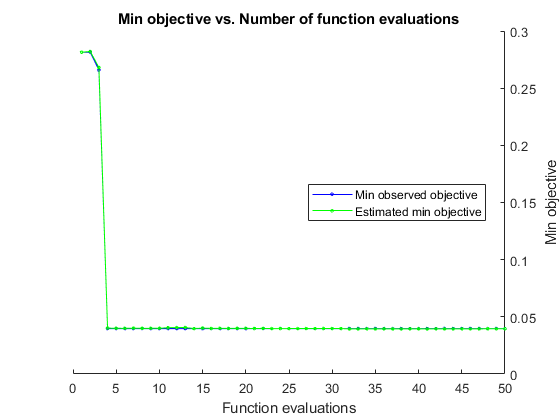


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 16.4855 seconds
Total objective function evaluation time: 5.6913

Best observed feasible point:
      prior      MaxNumSplit    MinLeafSize
    _________    ___________    ___________

    empirical         4              8     

Observed objective function value = 0.039735
Estimated objective function value = 0.039834
Function evaluation time = 0.11455

Best estimated feasible point (according to models):
      prior      MaxNumSplit    MinLeafSize
    _________    ___________    ___________

    empirical         1              6     

Estimated objective function value = 0.039568
Estimated function evaluation ti

% 2a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = accuracy)
% i) Define loss function
loss = @(params)kfoldLoss(fitctree(X_train, y_train, 'CVPartition', c, 'Reproducible', 1,...
                                     'prior', char(params.prior), ...
                                     'MaxNumSplits',params.MaxNumSplit, ...
                                     'MinLeafSize',params.MinLeafSize));

% ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

% iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1,...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

accuracy = 0.9460

precision = NaN

recall = 0

specificity = 1

fb = 0

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |     0.32604 |     0.12968 |     0.32604 |     0.32604 |      uniform |           15 |  correlation |      inverse |
|    2 | Accept |     0.43804 |      0.1289 |     0.32604 |     0.33277 |      uniform |            2 |  correlation |      inverse |
|    3 | Accept |     0.43046 |     0.12578 |     0.32604 |     0.33169 |      uniform |            2 |    euclidean | squaredinver |
|    4 | Best   |    0.040245 |     0.13191 |    0.040245 |   

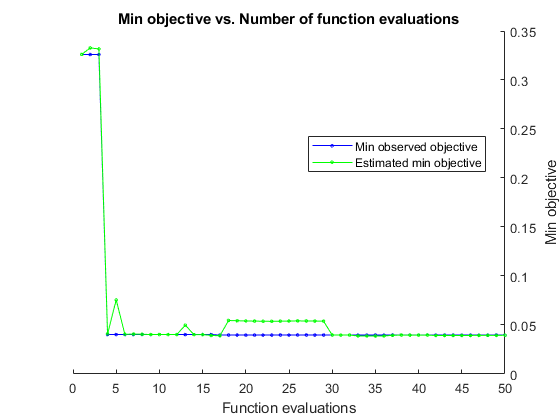


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 17.2475 seconds
Total objective function evaluation time: 6.2311

Best observed feasible point:
      prior      n        dst       dstWeight
    _________    __    _________    _________

    empirical    20    euclidean     inverse 

Observed objective function value = 0.039735
Estimated objective function value = 0.039766
Function evaluation time = 0.14648

Best estimated feasible point (according to models):
      prior      n        dst       dstWeight
    _________    __    _________    _________

    empirical    18    euclidean      equal  

% 2b) KNN: Bayesian Optimization (CV = k-fold, loss = accuracy)
% i) Define loss function
loss = @(params)kfoldLoss(fitcknn(X_train, y_train, 'CVPartition', c, ...
            'prior', char(params.prior), ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight)));

% ii) Optimize model
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);

% iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

accuracy = 0.9460

precision = NaN

recall = 0

specificity = 1

fb = 0

% ********** 3) Hyperparameter Tuning Models (CV = k-fold, loss = f-beta) **********

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.94444 |      0.1278 |     0.94444 |     0.94444 |    empirical |           24 |            5 |
|    2 | Best   |      0.8514 |       0.116 |      0.8514 |     0.85891 |      uniform |            2 |           17 |
|    3 | Best   |     0.81638 |     0.11314 |     0.81638 |     0.81642 |      uniform |            9 |           25 |
|    4 | Accept |           1 |     0.10002 |     0.81638 |     0.83336 |    empirical |            2 |           11 |
|    5 | Accept |     0.83009 |     0.12004 |   

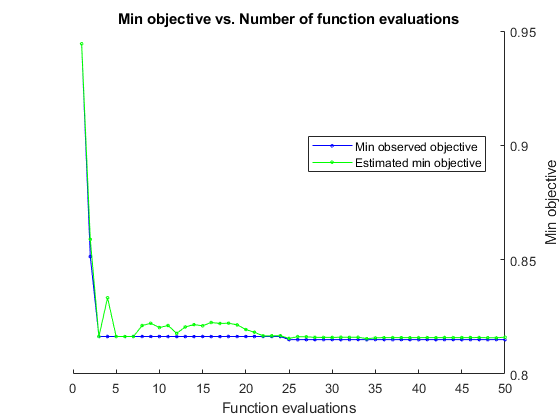


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 15.7241 seconds
Total objective function evaluation time: 5.719

Best observed feasible point:
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform        10             24     

Observed objective function value = 0.81503
Estimated objective function value = 0.81711
Function evaluation time = 0.11013

Best estimated feasible point (according to models):
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform        10              5     

Estimated objective function value = 0.81611
Estimated function evaluation time = 0.11428



% 3a) Decision Tree: Bayesian Optimization (CV = k-fold, loss = f-beta)
% i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c); % see helper function

% ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);


% iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

accuracy = 0.7658

precision = 0.1609

recall = 0.7925

specificity = 0.7643

fb = 0.2675

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |      0.8072 |     0.12311 |      0.8072 |      0.8072 |      uniform |            6 |    euclidean |      inverse |
|    2 | Accept |     0.85658 |     0.15522 |      0.8072 |     0.80916 |      uniform |           18 |  correlation |      inverse |
|    3 | Accept |           1 |     0.11705 |      0.8072 |     0.88792 |    empirical |           10 |    euclidean |      inverse |
|    4 | Accept |      0.9878 |     0.12219 |      0.8072 |   

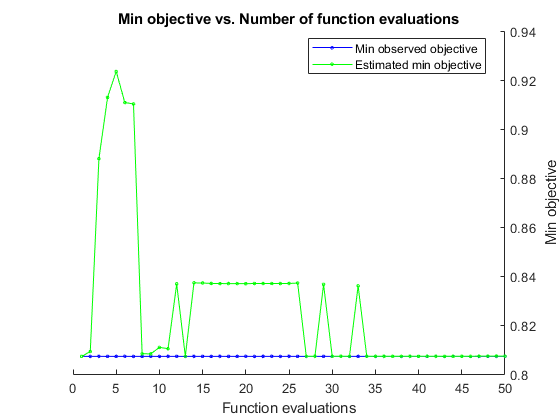


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 16.5829 seconds
Total objective function evaluation time: 6.1578

Best observed feasible point:
     prior     n       dst       dstWeight
    _______    _    _________    _________

    uniform    6    euclidean     inverse 

Observed objective function value = 0.8072
Estimated objective function value = 0.80731
Function evaluation time = 0.12311

Best estimated feasible point (according to models):
     prior     n       dst       dstWeight
    _______    _    _________    _________

    uniform    6    euclidean     inverse 

Estimated objective

% 3b) KNN: Bayesian Optimization (CV = k-fold, loss = f-beta)
% i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c); % see helper function

% ii) Optimize model
rng(0) % for reproducability
results = bayesopt(loss, ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);


% iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

accuracy = 0.8035

precision = 0.1316

recall = 0.4717

specificity = 0.8224

fb = 0.2058

% ********** 4) Hyperparameter Tuning Models (CV = statify, loss = f-beta) **********

% CV SPLITS (Stratified)
c = cvpartition(y_train,'KFold', 20, 'Stratify', true);

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |  MaxNumSplit |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.95349 |     0.12533 |     0.95349 |     0.95349 |    empirical |           11 |            3 |
|    2 | Best   |     0.85479 |    0.097642 |     0.85479 |     0.90405 |      uniform |            2 |           11 |
|    3 | Best   |     0.84412 |     0.12432 |     0.84412 |     0.84422 |      uniform |           22 |           18 |
|    4 | Accept |           1 |      0.1069 |     0.84412 |     0.84414 |    empirical |            5 |           17 |
|    5 | Accept |     0.94318 |     0.12353 |   

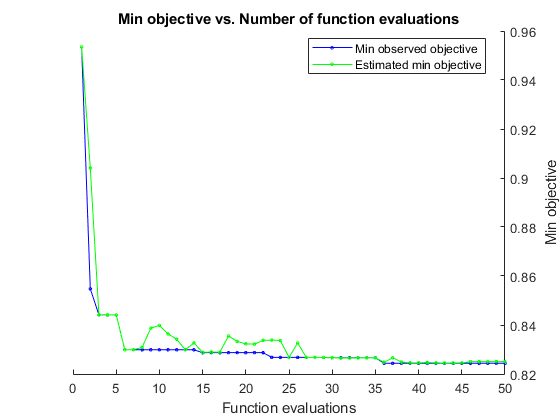


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 16.0147 seconds
Total objective function evaluation time: 5.8804

Best observed feasible point:
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform         9              9     

Observed objective function value = 0.82437
Estimated objective function value = 0.82567
Function evaluation time = 0.11335

Best estimated feasible point (according to models):
     prior     MaxNumSplit    MinLeafSize
    _______    ___________    ___________

    uniform         9             11     

Estimated objective function value = 0.82508
Estimated function evaluation time = 0.11521



% 4a) Decision Tree: Bayesian Optimization (CV = statify, loss = f-beta)
% i) Define loss function
loss = @(params)fb_loss_dt_cv(params,X_train,y_train, c); % see helper function

% ii) Optimize model
results = bayesopt(loss, ParamsDT,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);


% iii) Train optimized model on entire data set
z = bestPoint(results);
dt_best = fitctree(X_train, y_train, 'Reproducible', 1, ...
    'prior', char(z.prior), ...
    'MaxNumSplits', z.MaxNumSplit, ...
    'MinLeafSize', z.MinLeafSize);

% iv) Evaluate final model on test data
test_model(dt_best, X_test, y_test)

accuracy = 0.7811

precision = 0.1680

recall = 0.7736

specificity = 0.7815

fb = 0.2761

% 4b) KNN: Bayesian Optimization (CV = statify, loss = f-beta)
disp('***** Hyperparameter Tuning KNN (CV = statify, loss = f-beta) *****')

***** Hyperparameter Tuning KNN (CV = statify, loss = f-beta) *****



% i) Define loss function
loss = @(params)fb_loss_knn_cv(params,X_train,y_train, c) % see helper function

loss = function_handle with value:
    @(params)fb_loss_knn_cv(params,X_train,y_train,c)


|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |        prior |            n |          dst |    dstWeight |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |              |
|===================================================================================================================================|
|    1 | Best   |     0.97838 |     0.12748 |     0.97838 |     0.97838 |    empirical |            5 |    euclidean |      inverse |
|    2 | Best   |     0.84273 |     0.12251 |     0.84273 |     0.90555 |      uniform |           13 |    euclidean |      inverse |
|    3 | Accept |     0.86194 |     0.12793 |     0.84273 |     0.86468 |      uniform |           17 |       cosine |        equal |
|    4 | Accept |     0.98765 |     0.13503 |     0.84273 |   

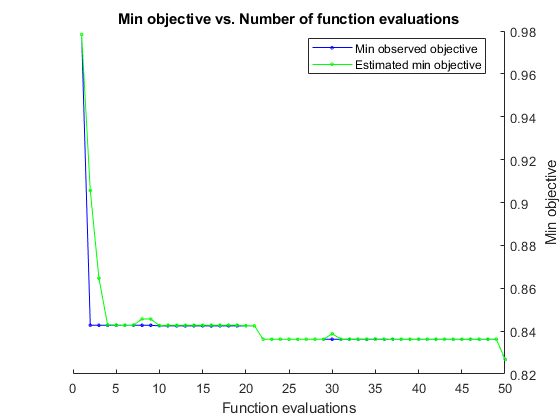


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 50 reached.
Total function evaluations: 50
Total elapsed time: 17.214 seconds
Total objective function evaluation time: 6.2624

Best observed feasible point:
     prior     n       dst         dstWeight   
    _______    _    _________    ______________

    uniform    9    euclidean    squaredinverse

Observed objective function value = 0.82687
Estimated objective function value = 0.82695
Function evaluation time = 0.11791

Best estimated feasible point (according to models):
     prior     n       dst         dstWeight   
    _______    _    _________    ______________

    uniform    9    euclidean    squar


% ii) Optimize model
results = bayesopt(@(params)fb_loss_knn_cv(params,X_train,y_train, c), ParamsKNN,...
    'AcquisitionFunctionName','expected-improvement-plus', 'NumSeedPoints', 10, ...
    'MaxObjectiveEvaluations', 50, 'GPActiveSetSize', 1000, 'Verbose',1);


% iii) Train optimized model on entire data set
z = bestPoint(results);
knn_best = fitcknn(X_train, y_train, ...
    'prior', char(z.prior), ...
    'NumNeighbors', z.n, ...
    'Distance', char(z.dst), ...
    'DistanceWeight',char(z.dstWeight));

% iv) Evaluate final model on test data
test_model(knn_best, X_test, y_test)

accuracy = 0.7648

precision = 0.1292

recall = 0.5849

specificity = 0.7750

fb = 0.2116

function test_model(model, X_test, y_test)
    y_pred = predict(model, X_test);
    cmat = confusionmat(y_test, y_pred);  % Confusion matrix
    %confusionchart(cmat);
    [accuracy, precision, recall, specificity, fb] = binary_eval_metrics(y_test, y_pred) 
end

% Decision tree loss loss function CV
function fb = fb_loss_dt_cv(params, X_train, y_train, cv_part)
        % Train model with selected parameters
        model = fitctree(X_train, y_train, 'CVPartition', cv_part, 'Reproducible', 1,...
             'prior', char(params.prior), ...
             'MaxNumSplits',params.MaxNumSplit, ...
             'MinLeafSize',params.MinLeafSize);
               
        % Calculate F1 score
        y_pred = kfoldPredict(model);
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% KNN function CV
function fb = fb_loss_knn_cv(params, X_train, y_train, cv_part)
        model = fitcknn(X_train, y_train, 'CVPartition', cv_part, ...
            'prior', char(params.prior), ...
            'NumNeighbors', params.n, ...
            'Distance', char(params.dst), ...
            'DistanceWeight',char(params.dstWeight));
        
        % Calculate F-beta score
        y_pred = kfoldPredict(model);   
        [~, ~, ~, ~, fb] = binary_eval_metrics(y_train, y_pred);
        fb = 1-fb;  % Convert to f1-"loss"
end

% Evaluation metrics for binary classification
function [acc, prec, rec, spec, fb] = binary_eval_metrics(y_test, y_pred)
    cmat = confusionmat(y_test, y_pred);
    tn = cmat(1,1);
    fn = cmat(2,1);
    tp = cmat(2,2);
    fp = cmat(1,2);
    %confusionchart(cmat);

    % Statistics of interest for confusion matrix
    b = 1; % beta < 1 favours precision over recall.
    prec = tp / (tp + fp); % precision
    rec = tp / (tp + fn); % recall
    spec = tn / (tn + fp); % specificity
    acc = (tp + tn) / (tn + fn + tp + fp);
    fb = ((1+b^2)*tp) / ((1+b^2)*tp + b^2 * fp + fn); % (see https://en.wikipedia.org/wiki/F-score)
end
%#ok<*ASGLU,*NOPRT> 